Introduction to Control Systems - Simulation

## Exercise 2 First-Order Systems

clear sim
tank_sim = sim('ME419_Ex1_2.slx') ;
max_TD = max(tank_sim.Tank_Drop); % Maximum Tank Drop [in]
Tau_TD = 0.632*max_TD; % [in] Tank Level at 63.2% (which is located at 1 Tau)
index = find(tank_sim.Tank_Drop>=Tau_TD-Tau_TD*0.05 & tank_sim.Tank_Drop<=Tau_TD+Tau_TD*0.05); % index of the time constant
Time_Const = tank_sim.tout(index) % [s] Time Constant 

Time_Const = 1.9942

### Diagrams

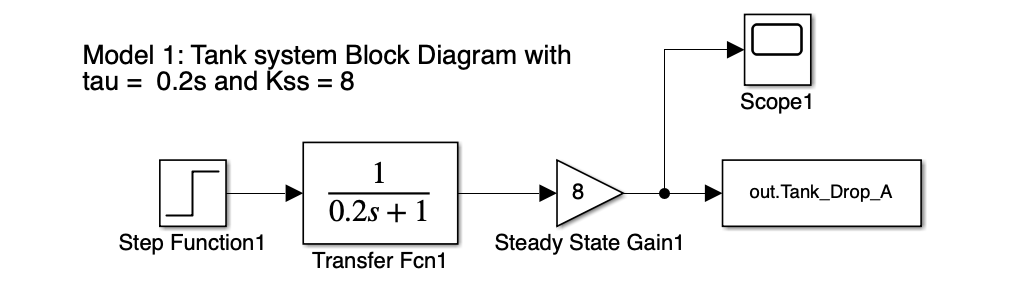

Figure 1.2.1: Model A water tank system diagram 

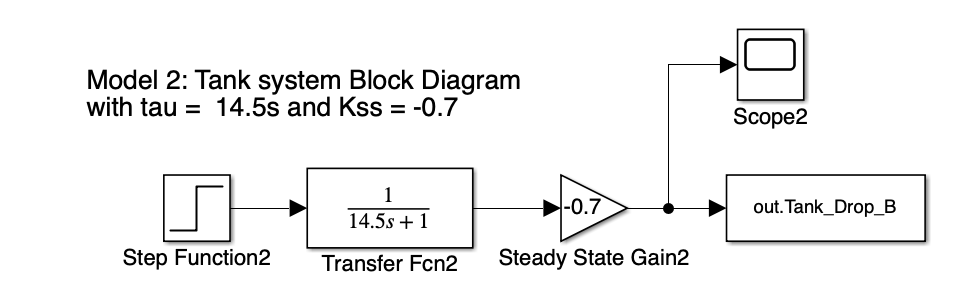

Figure 1.2.2: Model B water tank system diagram 

### Plots

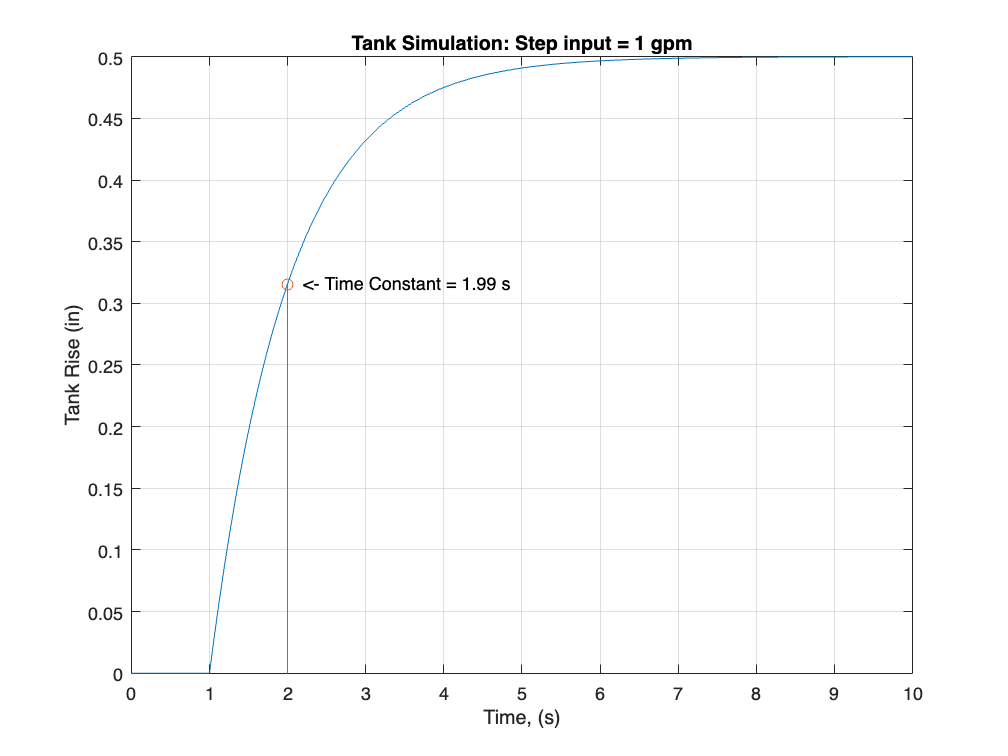

figure()
plot(tank_sim.tout, tank_sim.Tank_Drop) % Plot of Simulation Results
title('Tank Simulation: Step input = 1 gpm')
xlabel('Time, (s)')
ylabel('Tank Rise (in)')
grid on
hold on
stem(Time_Const,tank_sim.Tank_Drop(index)) % Location of 1 Tau
text(2.2,0.317,'<- Time Constant = 1.99 s')
hold off

#### System 1.2A

Tau_A = 0.8/4; % [seconds], 4Tau = 0.8, therefore, 1Tau = 0.8/4
max_TD_A = max(tank_sim.Tank_Drop_A); % [in] Maximum Tank Change 
Tau_TD_A = 0.632*max_TD_A; % [in] Tank Level at 63.2% (which is 1 Tau)
index_A = find(tank_sim.Tank_Drop_A>=Tau_TD_A-Tau_TD_A*0.05 & tank_sim.Tank_Drop_A<=Tau_TD_A+Tau_TD_A*0.05) % Located of 1 Tau in data set w/ a tolerance (where Tau is approximately =)

index_A = 14

Time_Const_A = tank_sim.tout(index_A) % [s] Time Constant

Time_Const_A = 1.2157

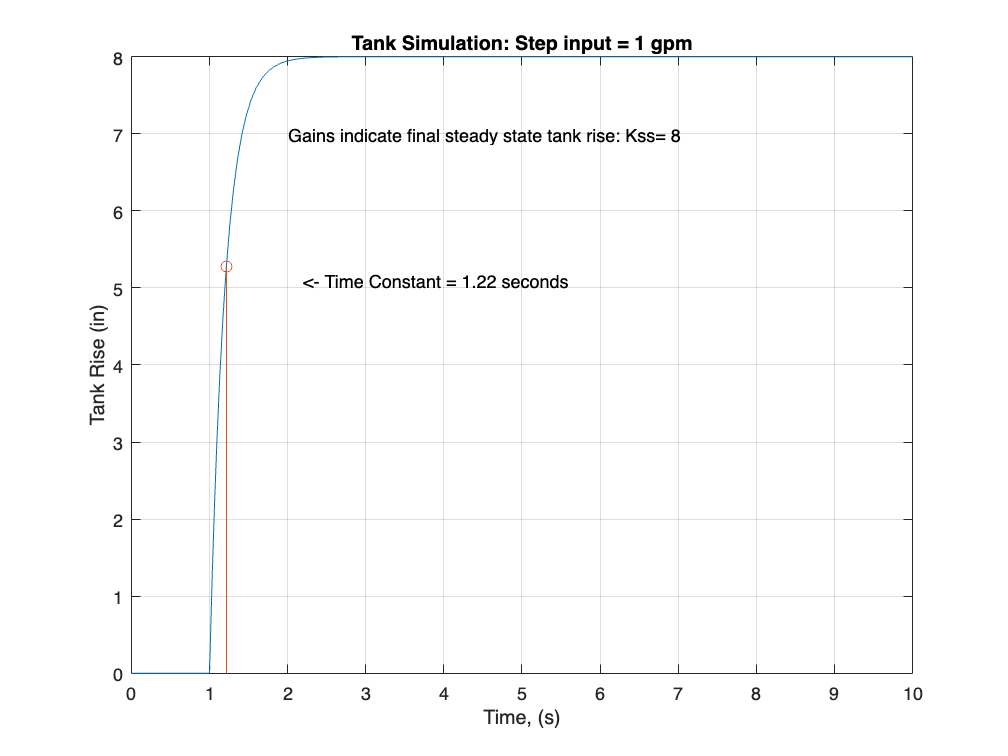

figure()
plot(tank_sim.tout, tank_sim.Tank_Drop_A) % Plot of Simulation Results
title('Tank Simulation: Step input = 1 gpm')
xlabel('Time, (s)')
ylabel('Tank Rise (in)')
grid on
hold on
stem(Time_Const_A,tank_sim.Tank_Drop_A(index_A))  % Location of 1 Tau
text(2.2,5.1,'<- Time Constant = 1.22 seconds')
text(2,7,'Gains indicate final steady state tank rise: Kss= 8')
hold off

#### System 1.2B

clear sim
t = 80 ; % Defined Time Span
tank_sim = sim('ME419_Ex1_2.slx',t) ;

Settle_T_B = 58 ; % Settling Time of System (4Tau)
Tau_A = Settle_T_B/4; % Time Constant

max_TD_B = min(tank_sim.Tank_Drop_B); % Maximum Tank Drop
Tau_TD_B = 0.632*max_TD_B; % Tank Level at 63.2% which is 1 Tau
index_B = find(tank_sim.Tank_Drop_B<=Tau_TD_B-Tau_TD_B*0.02 & tank_sim.Tank_Drop_B>=Tau_TD_B+Tau_TD_B*0.02);
Time_Const_B = tank_sim.tout(index_B)

Time_Const_B = 15.4932

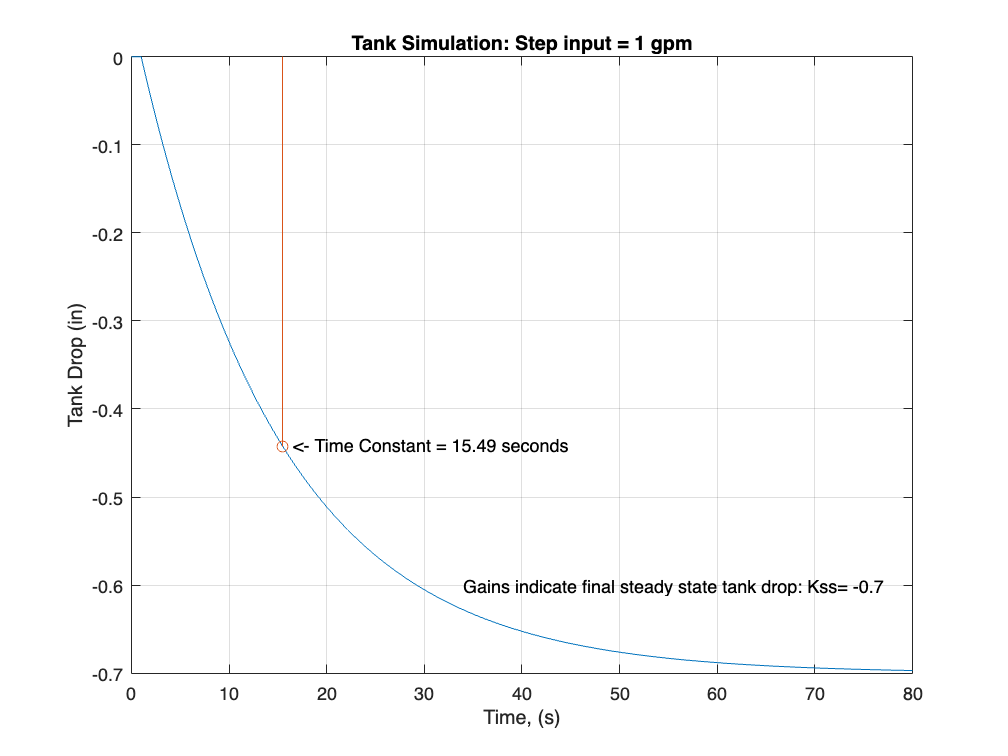

figure()
plot(tank_sim.tout, tank_sim.Tank_Drop_B) % Plot of Simulation Results
title('Tank Simulation: Step input = 1 gpm')
xlabel('Time, (s)')
ylabel('Tank Drop (in)')
grid on
hold on
stem(Time_Const_B,tank_sim.Tank_Drop_B(index_B))  % Location of 1 Tau
text(16.6,-0.44,'<- Time Constant = 15.49 seconds')
text(34,-0.6,'Gains indicate final steady state tank drop: Kss= -0.7')
hold off

### Questions

*(a) Does the system behave as expected?*

We expected the system to reach the final value of 0.5 inches in a non linear way, similar to a DC motor response which is what we

observed here.

*(b) How long does the system take to reach 63.2% of its final value?*

The sytema reaches 63.2% of its final value at a time of two seconds

*(c) What was the size of the input step?*

The input step is the flowrate and we used a unit step function that goes from 0 to 1 gal/min. 

*(d) What size output change did it produce?*

The step response approaches 0.5 inches. 

*(e) How could you change the system to produce in the same time frame a steady state responce that is twice as great as the step input?*

Either change step input final value to double initial value or change gain to double its initial value. 

## Exercise 3 Second-Order Systems

clear sim
%t = 80 ; % Defined Time Span
mass_damper_sim = sim('ME419_EX1_3.slx') ;
Kss_A = 3;
freq_A = 1; %hz
Wn_A = freq_A*2*pi;
zeta_A = 0.15;
Wd_A = Wn_A*sqrt(1-zeta_A^2);

Kss_B = 3; %steady state gain
freq_B = 1; % hz
Wn_B = freq_B*2*pi; % natural frequency
zeta_B = 0.15*2; % damping ratio
Wd_B = Wn_B*sqrt(1-zeta_B^2); % damping frequency
Kss_C = 3;
freq_C = 1*2; %hz
Wn_C = freq_C*2*pi;
zeta_C = 0.15;
Wd_C = Wn_C*sqrt(1-zeta_C^2);

### Model A Parameters

% checks that the steady state values before and after the step response
% are as expected
ss_change_A = mass_damper_sim.A;
check_ss_gain_A = round((ss_change_A(end)-ss_change_A(1))/1) % checks that the plot agrees with Kss = 3

check_ss_gain_A = 3

% Compares that the simulated and calculated %OS are the similar
percOS_A = exp(-zeta_A*pi/sqrt(1-zeta_A^2));
dataOS_A = (max(ss_change_A)-3)/3;

disp("Calculated Overshoot")

Calculated Overshoot


disp(percOS_A)

    0.6209



disp("Simulated Overshoot")

Simulated Overshoot


disp(dataOS_A)

    0.6208



% this block of code finds the first and second peaks on the graph in order
% to find the damping frequency
check_osc = ss_change_A(islocalmax(ss_change_A)~=0); % finds the local maximums of the plot
val1 = find(check_osc(1) == ss_change_A);
val2 = find(check_osc(2) == ss_change_A);
data_damping_freq = 2*pi/(mass_damper_sim.tout(val2) - mass_damper_sim.tout(val1));

disp('calculated damping frequency in rad/s:')

calculated damping frequency in rad/s:


disp(Wd_A)

    6.2121



disp('damping frequency from simulation plot in rad/s:')

damping frequency from simulation plot in rad/s:


disp(data_damping_freq)

    6.2065



### Model B Parameters

Doubling the damping ratio should decrease the OS percentage.

ss_change_B = mass_damper_sim.A1;
percOS_B = exp(-zeta_B*pi/sqrt(1-zeta_B^2))

percOS_B = 0.3723

dataOS_B = (max(ss_change_B)-3)/3

dataOS_B = 0.3723

### Model C Parameters

Doubling the oscilllation frequency should increase speed at which the system reaches steady state. This should be the case because the system should lose energy more rapidly due the the faster oscillations

ss_change_C = mass_damper_sim.A2;
check_osc = ss_change_C(islocalmax(ss_change_C)~=0);
val1 = find(check_osc(1) == ss_change_C);
val2 = find(check_osc(2) == ss_change_C);
data_damping_freq = 2*pi/(mass_damper_sim.tout(val2) - mass_damper_sim.tout(val1))

data_damping_freq = 12.2320

### Diagrams

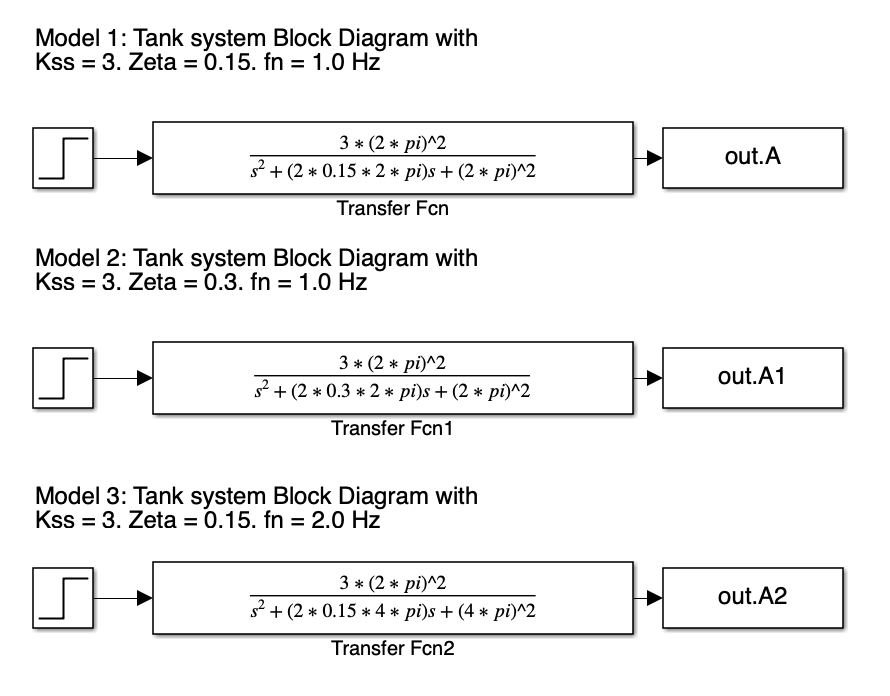

Figure 1.3 Block Diagrams of All Three Systems

### Plots

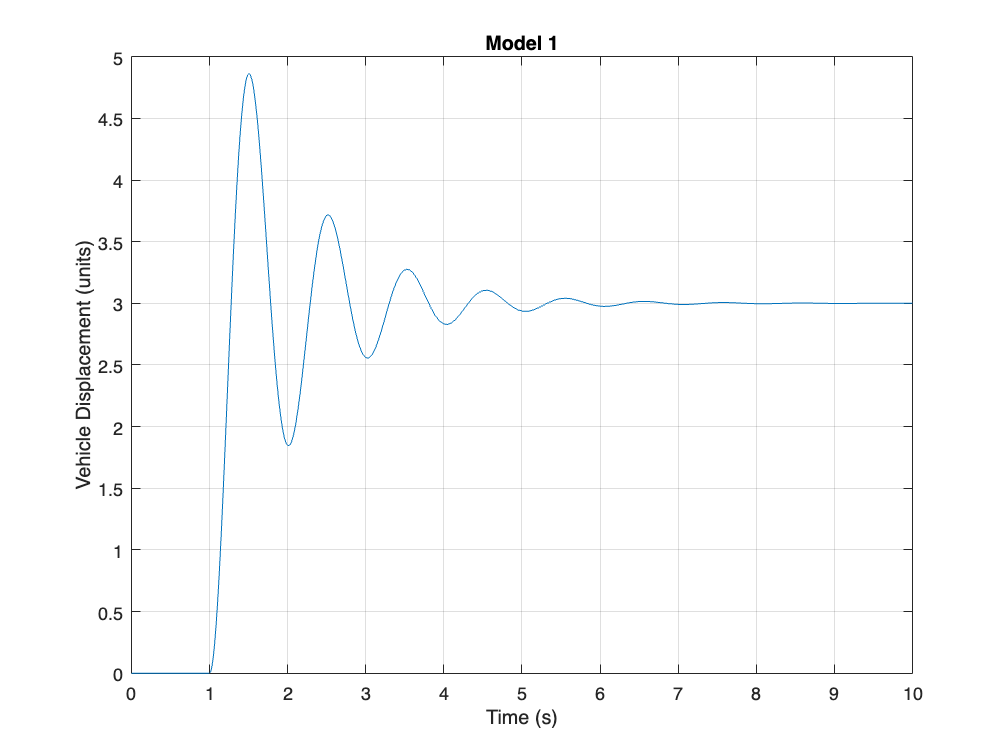

figure()
plot(mass_damper_sim.tout, mass_damper_sim.A)
title('Model 1')
xlabel('Time (s)')
ylabel('Vehicle Displacement (units)')
grid on

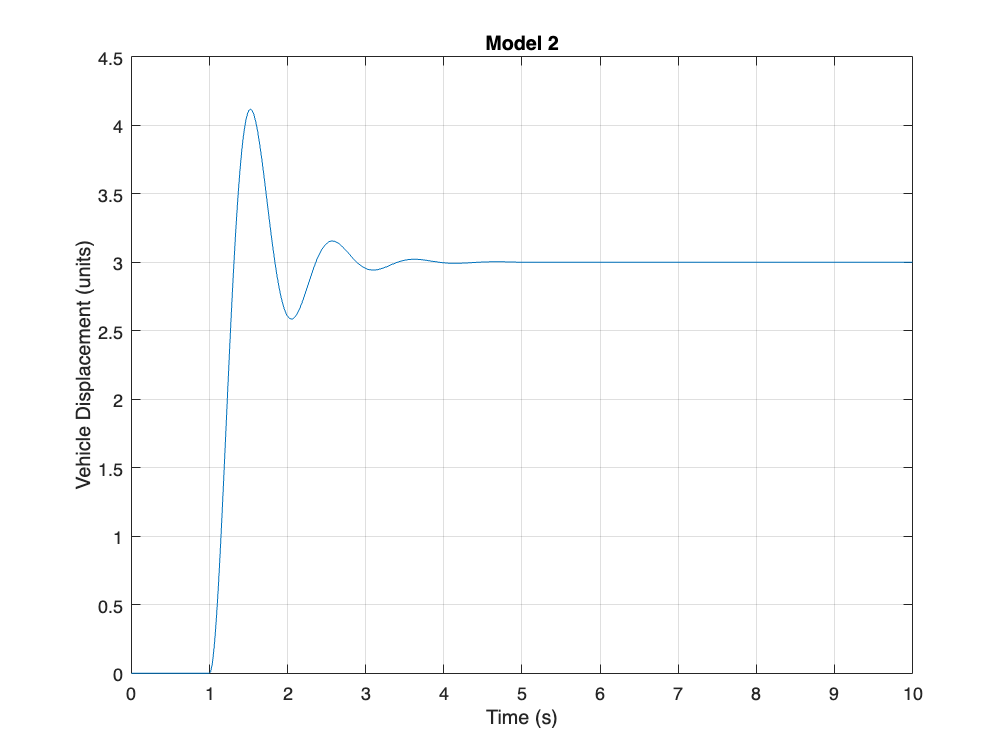


figure()
plot(mass_damper_sim.tout, mass_damper_sim.A1)
title('Model 2')
xlabel('Time (s)')
ylabel('Vehicle Displacement (units)')
grid on

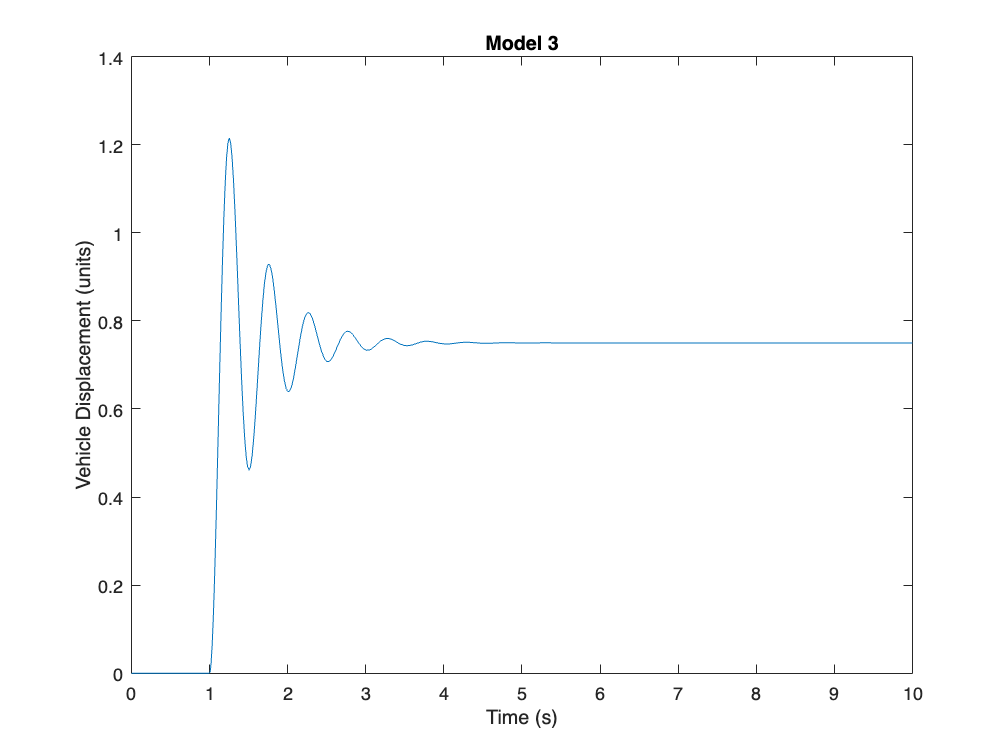


figure()
plot(mass_damper_sim.tout, mass_damper_sim.A2)
title('Model 3')
xlabel('Time (s)')
ylabel('Vehicle Displacement (units)')

### Questions

#### Model 1

Simulated Kss = 3, Calculated Kss = 3

Simulated %OS = 0.6208, Calculated %OS = 0.6209

Simulated Wd = 6.2065 rad/s, Calculated Wd = 6.2121 rad/s/

#### Model 2

Doubling the damping ratio should decrease the OS percentage.

Simulated %OS = 0.3723, Calculated %OS = 0.3723

#### Model 3

Doubling the oscilllation frequency should increase speed at which the system reaches steady state. This should be the case because the system should lose energy more rapidly due the the faster oscillations

Model 1 reaches steady state in approx. 7 seconds

Model 3 reaches steady state in approx. 4 seconds

## Exercise 5

Using Simulink to model a PID controller by itself with no plant or feedback.

PID = sim('ME419_EX1_5.slx',10) ; % PID control

### Diagram

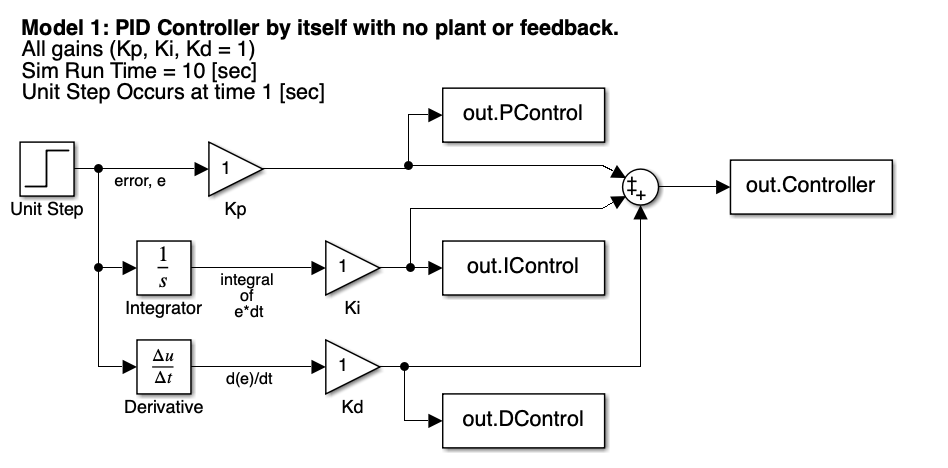

Figure 1.5 PID Controller by itself

### Plots

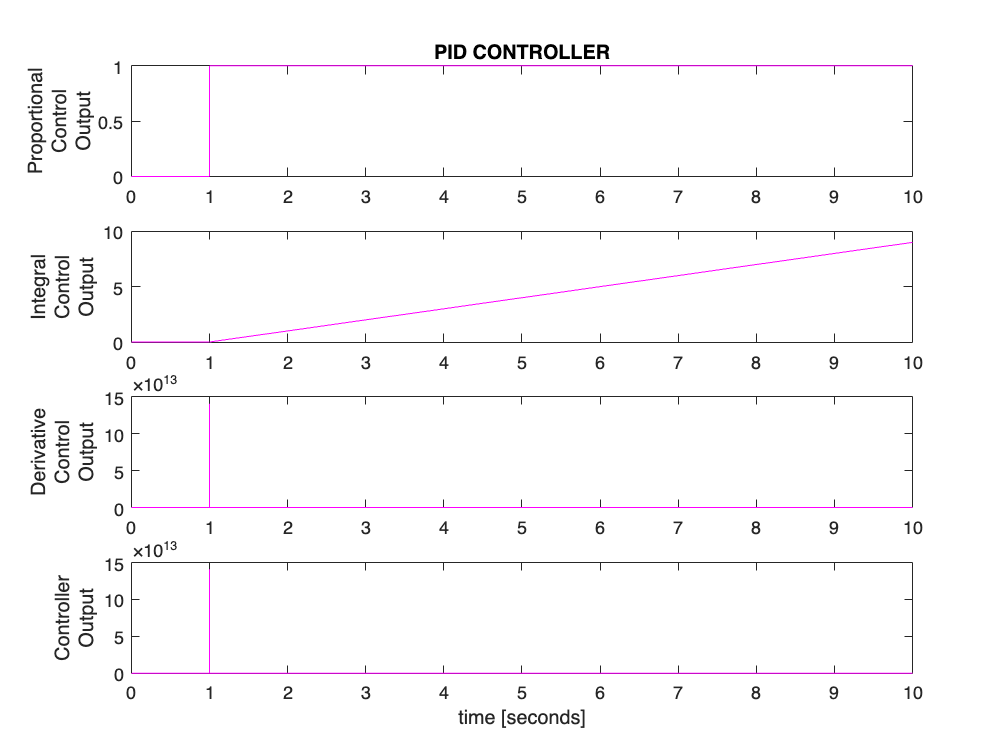

figure() % Plot of Simulation Results
subplot(4,1,1) 
plot(PID.tout, PID.PControl,'Color','m') % Proportional Control Only
title('PID CONTROLLER')
ylabel({'Proportional';'Control';'Output'})
subplot(4,1,2)
plot(PID.tout, PID.IControl,'Color','m') % Integral Control Only
ylabel({'Integral';'Control';'Output'})
subplot(4,1,3)
plot(PID.tout, PID.DControl,'Color','m') % Derivative Control Only
ylabel({'Derivative';'Control';'Output'})
subplot(4,1,4)
plot(PID.tout, PID.Controller,'Color','m') % Total Controller Action
ylabel({'Controller';'Output'})
xlabel('time [seconds]')

### Questions

*How do they (the plots of the controller actions) behave over time?*

The slope of the proportional control output is infinite at a time of 1 second, therefore, the large increase on the plot makes sense, as the output goes from zero to 1 in that instance. After t = 1 seconds, the output stays at 1. The output is essentially the error since the proportional gain is 1. 

Since the integral control output is the integral of the error, and the integral gain is 1, it makes sense that this slope is an increasing line after a time of t=1 seconds. This means that the output is changing at the same rate from 1 to 10 seconds. 

Since the derivative control output is the derivative of the error, and the derivative gain is 1, it makes sense that the behavior is the same as the proportional control output at t = 1 seconds. However, since there is no change in error after 1 second, the derivative output is 0. 

## Exercise 6

Simulated system with controllers to see how controllers work.

Tank_Control = sim('ME419_EX1_6.slx',60) ; % Tank Control

### Ex 6 Part A - Proportional Only Control

#### Diagram

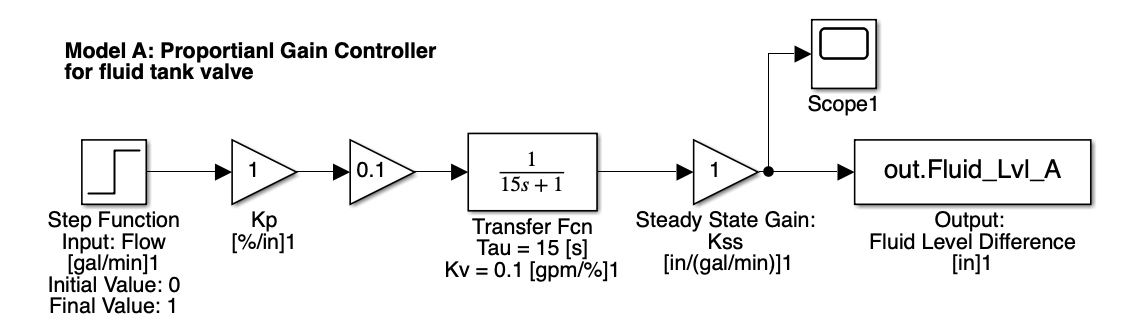

Figure 1.6.1 Part A Proportional Only Controller

#### Plot

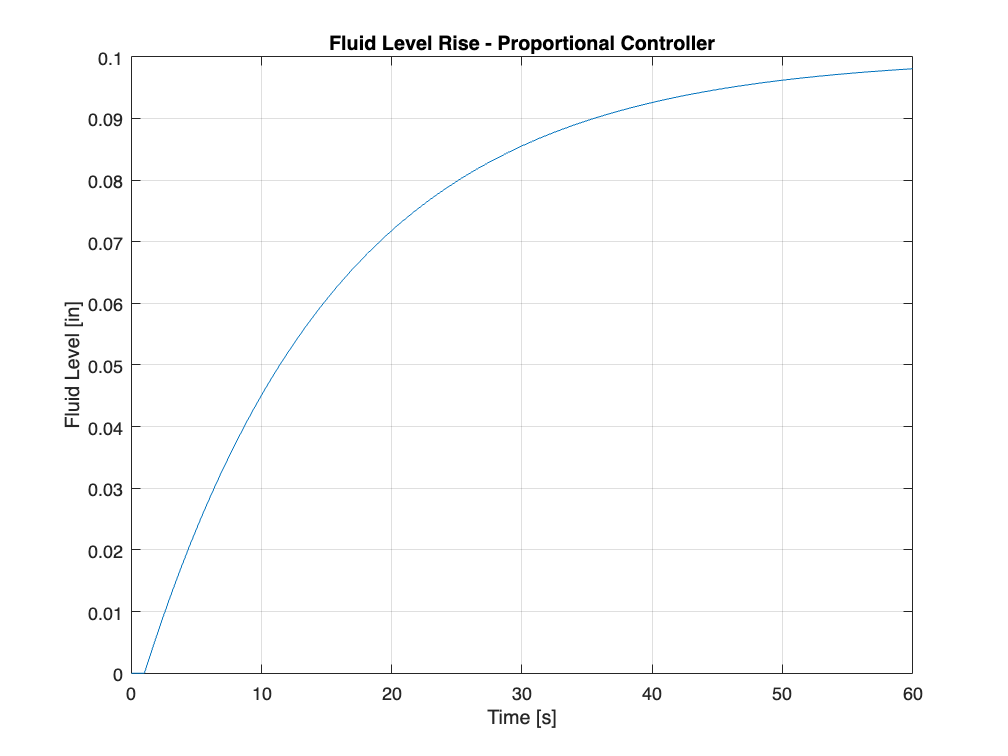

figure()
plot(Tank_Control.tout, Tank_Control.Fluid_Lvl_A)
ylabel('Fluid Level [in]')
xlabel('Time [s]')
title('Fluid Level Rise - Proportional Controller')
grid on

#### Questions

- What does the step response look like? You may be surprised by the results

- What is the steady-state gain of the closed-loop system compared with the system state gain of just the tank alone?

### Ex 6 Part B

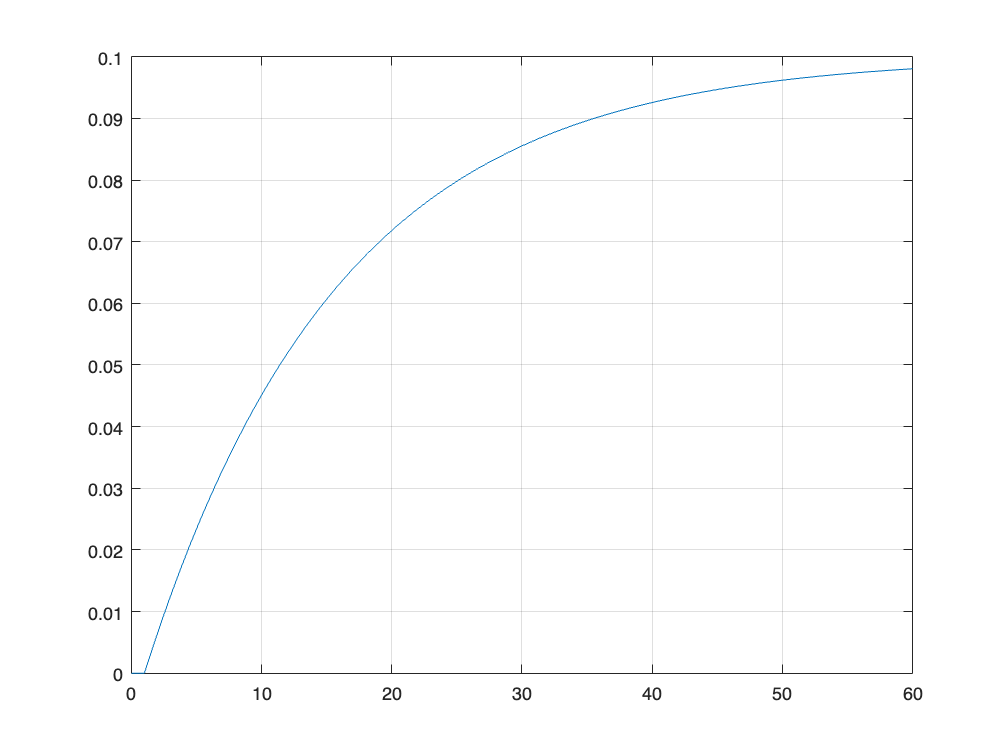

figure()
plot(Tank_Control.tout, Tank_Control.Fluid_Lvl_B)
grid on

### Ex 6 Part C

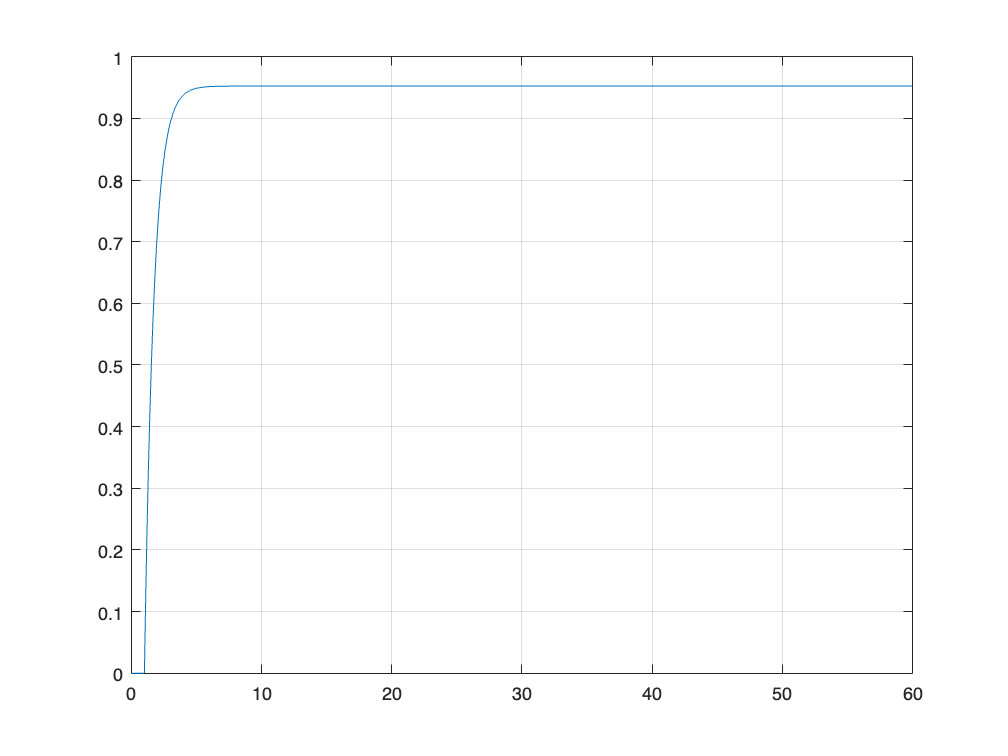

figure()
plot(Tank_Control.tout, Tank_Control.Fluid_Lvl_C)
grid on

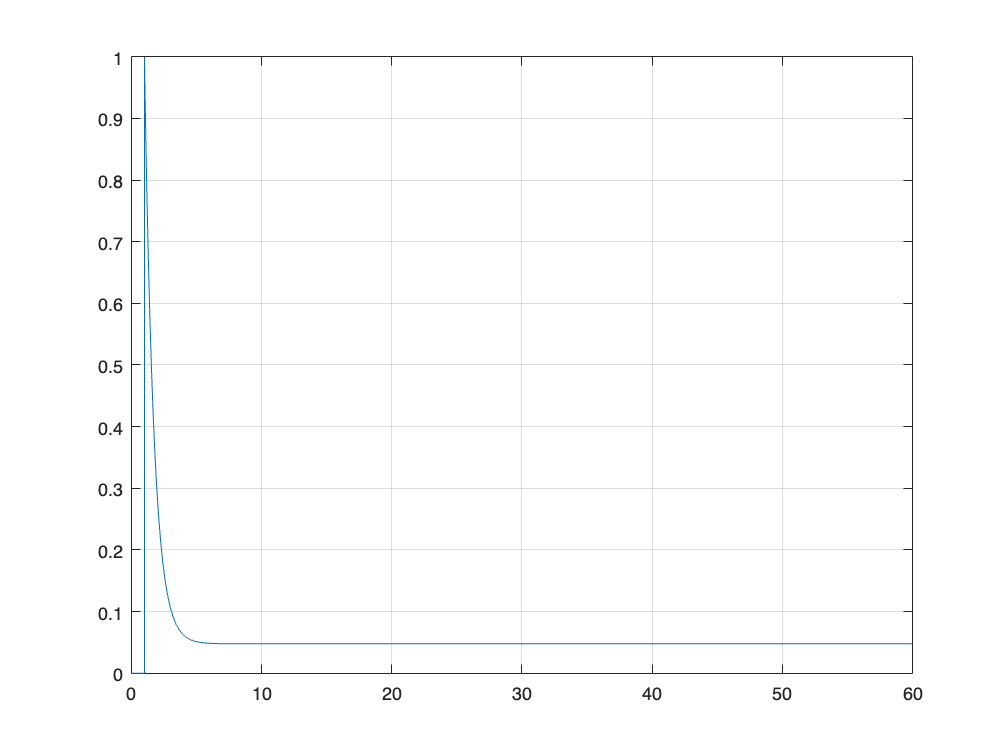


figure()
plot(Tank_Control.tout, Tank_Control.Error_C)
grid on

### Ex 1_6 Part D

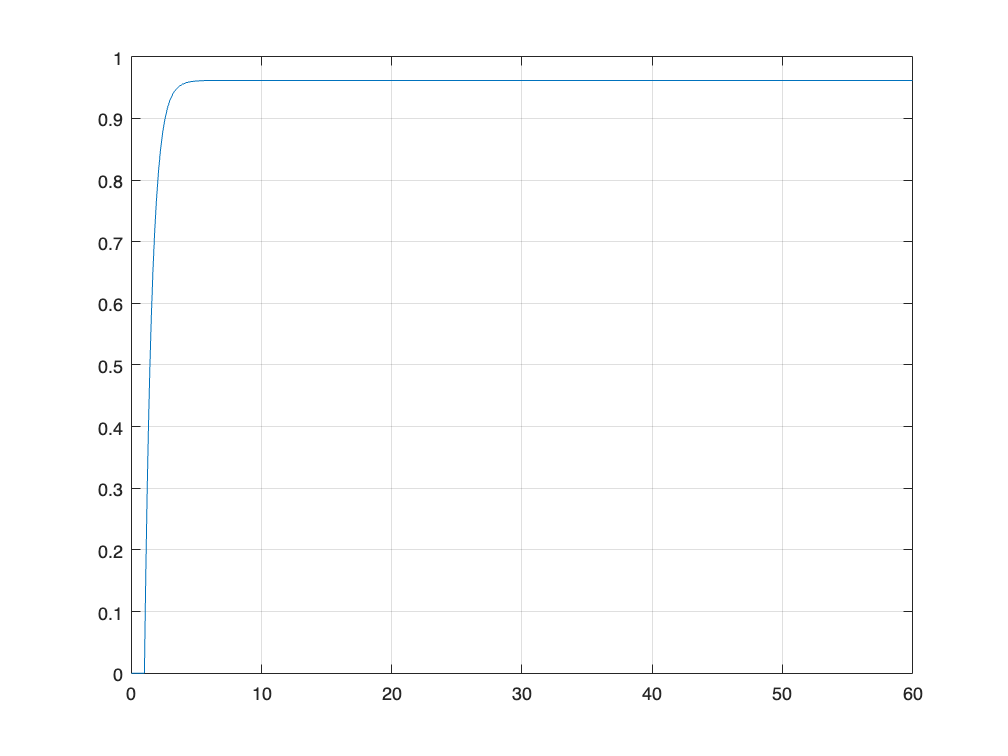

figure() % Output
plot(Tank_Control.tout, Tank_Control.Fluid_Lvl_D)
grid on

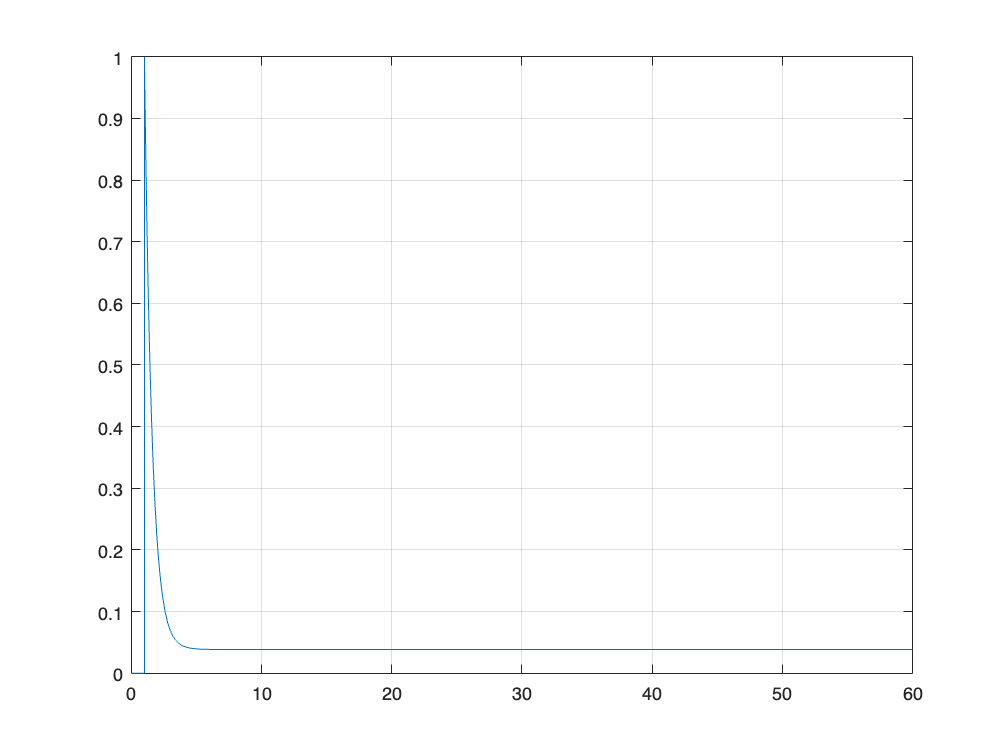


figure() % Error
plot(Tank_Control.tout, Tank_Control.Error_D)
grid on

### Ex 1_6 Part E

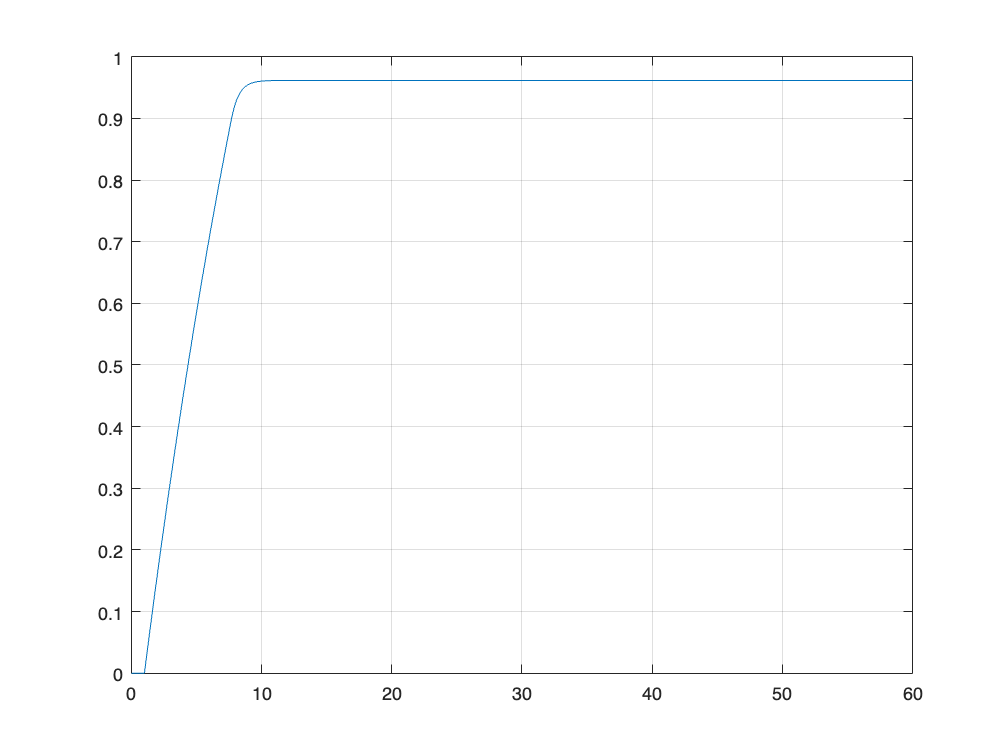

figure() % Error
plot(Tank_Control.tout, Tank_Control.Fluid_Lvl_E)
grid on

### Ex 1_6 Part F

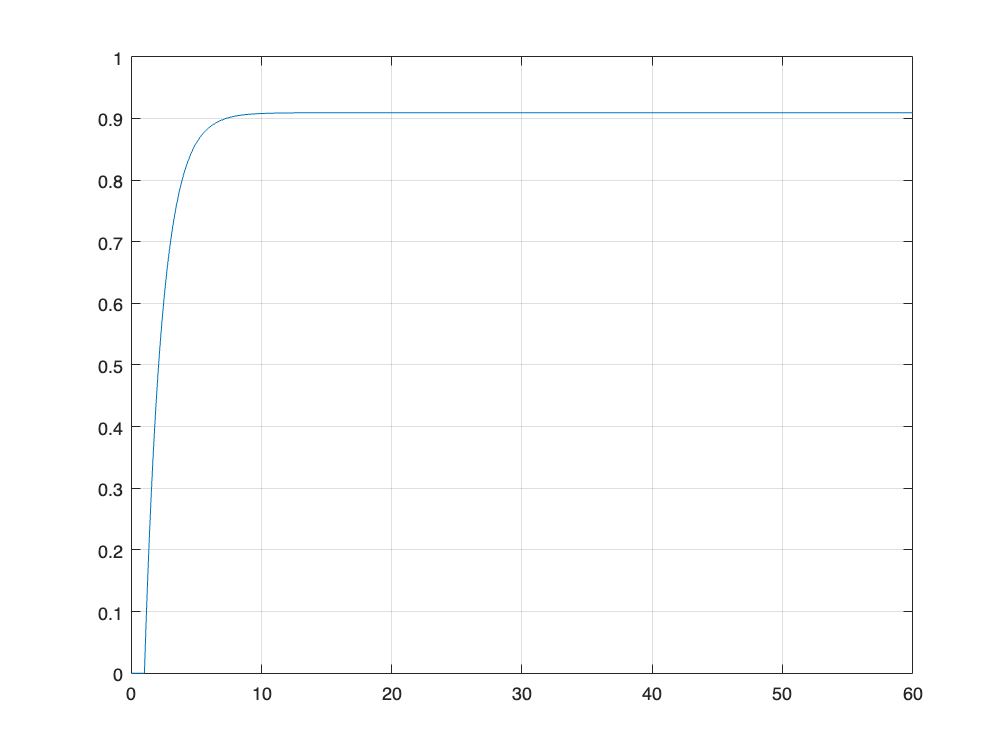

figure() % Error
plot(Tank_Control.tout, Tank_Control.Fluid_Lvl_F)
grid on

## Exercise 7

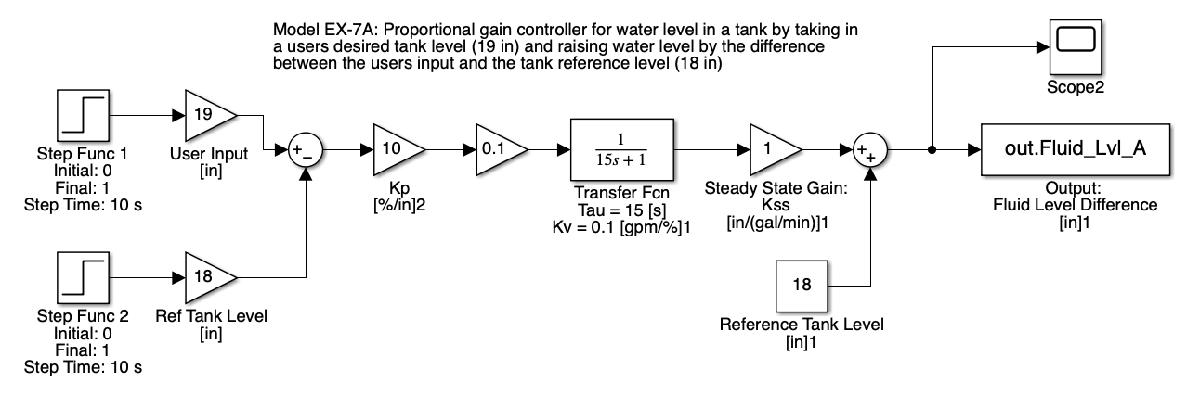

Figure 1.7.A Modified System Desired Tank Level as 19 in.

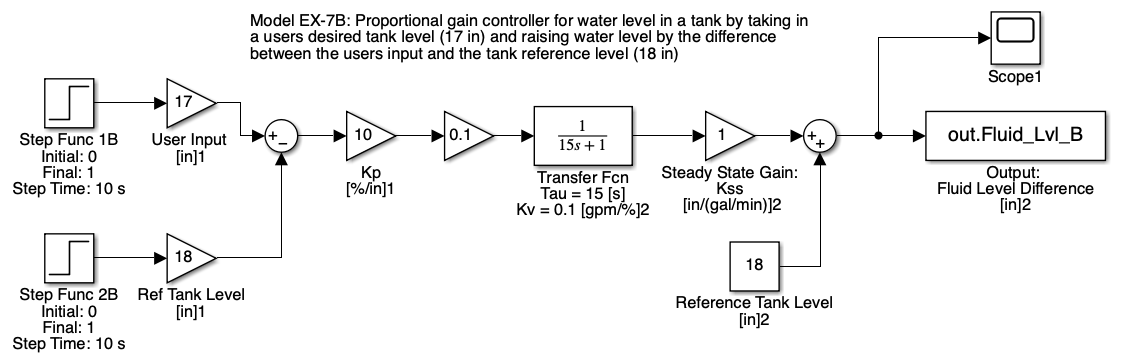

Figure 1.7.B Modified System Desired Tank Level as 17 in.

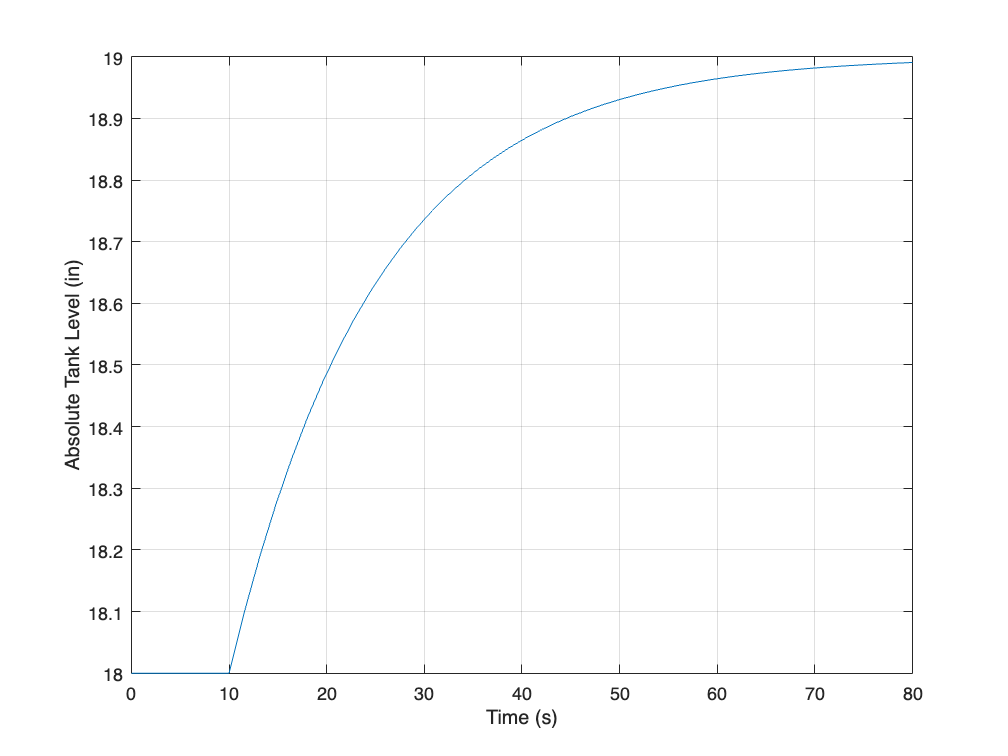

P7 = sim('ME419_EX1_7.slx',80) ; % P control

figure()
plot(P7.tout, P7.Fluid_Lvl_A)
ylabel('Absolute Tank Level (in)')
xlabel('Time (s)')
grid on

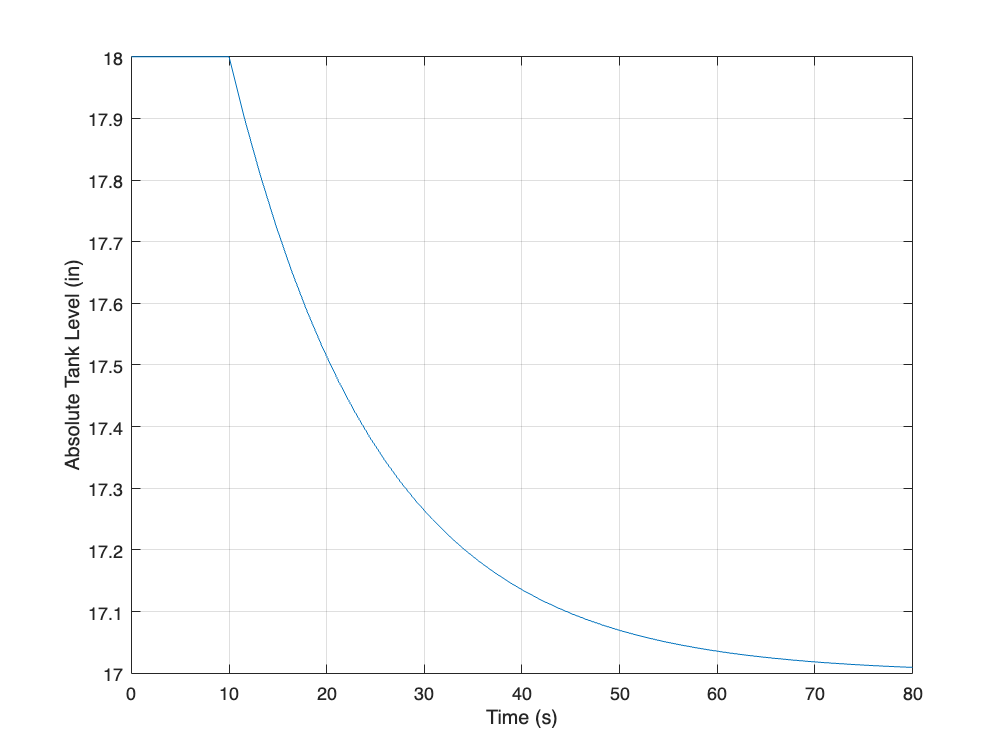

figure()
plot(P7.tout, P7.Fluid_Lvl_B)
ylabel('Absolute Tank Level (in)')
xlabel('Time (s)')
grid on

## Exercise 8

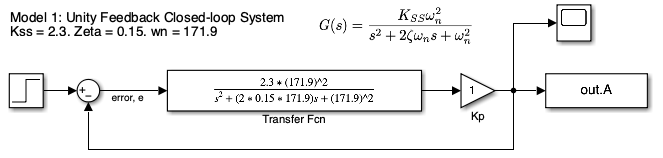

Figure 1.8.A Second Order System with P-Only Control

P8 = sim('ME419_EX1_8.slx',1.5) ; % P control

### Part 8A

zeta_8A = 0.15 ; % Damping Coefficicent
wn_8A = 171.9 ; % Natural Frequency
Kss_gain = 2.3 ; % Steady State Gain

Since zeta_8A  = 0.15 is between 0 and 1, the system is underdamped and oscillates. 

#### Calculated Values

wd_8B = wn_8A*sqrt(1-zeta_8A^2) % [rad/s] Damping Frequency - Calculated

wd_8B = 169.9551

percent_OS_8B_calc = exp(-zeta_8A*pi/sqrt(1-(zeta_8A^2)))*100 % Percent Overshoot - Calculated

percent_OS_8B_calc = 62.0871

#### Simulated Values 

sim_data_8A = P8.A ;
Kss_gain_8A_sim = ((sim_data_8A(end)-sim_data_8A(1))/1) % Kss

Kss_gain_8A_sim = 0.6970

percent_OS_8A_sim = ((max(sim_data_8A)-sim_data_8A(end))/sim_data_8A(end))*100 % Percent Overshoot - Simulation

percent_OS_8A_sim = 77.0378

% this block of code finds the first and second peaks on the graph in order
% to find the damping frequency (wd from sim)
check_osc_8A = sim_data_8A(islocalmax(sim_data_8A)~=0); % finds the local maximums of the plot
val1_8A = find(check_osc_8A(1) == sim_data_8A);
val2_8A = find(check_osc_8A(2) == sim_data_8A);
wd_8A_sim = 2*pi/(P8.tout(val2_8A) - P8.tout(val1_8A)) % [rad/s] Damping Frequency - Calculated

wd_8A_sim = 291.6404

#### Plot

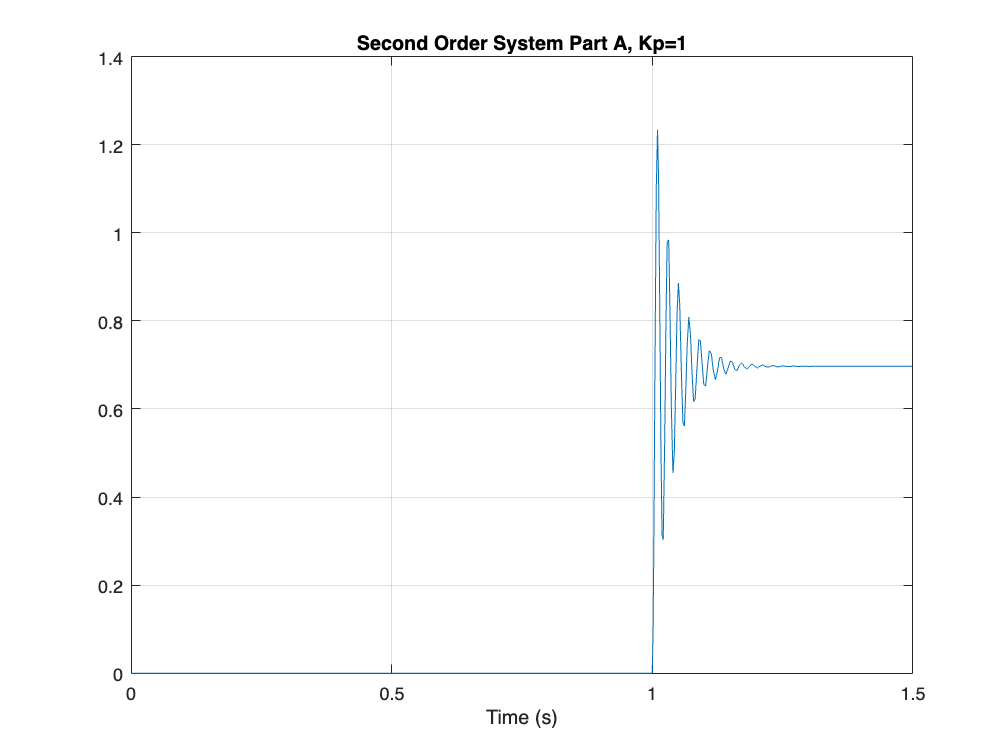

figure()
plot(P8.tout, P8.A)
title('Second Order System Part A, Kp=1')
xlabel('Time (s)')
grid on

We can observe in the above graph that the simulated system is in fact underdamped and oscillates.

### Part 8B

This system has the same initial parameters as part B. Again, since zeta_8B  = 0.15 is between 0 and 1, the system is underdamped and should oscillate. 

#### Calculated Values

The calculated values are the same as part A but they are inclded below for ease of comparison.

wd_8B = wn_8A*sqrt(1-zeta_8A^2) % [rad/s] Damping Frequency - Calculated

wd_8B = 169.9551

percent_OS_8B_calc = exp(-zeta_8A*pi/sqrt(1-(zeta_8A^2)))*100 % Percent Overshoot - Calculated

percent_OS_8B_calc = 62.0871

#### Simulated Values 

sim_data_8B = P8.B ;
Kss_gain_8B_sim = ((sim_data_8B(end)-sim_data_8B(1))/1) % Kss

Kss_gain_8B_sim = 0.8237

percent_OS_8B_sim = ((max(sim_data_8B)-sim_data_8B(end))/sim_data_8B(end))*100 % Percent Overshoot - Simulation

percent_OS_8B_sim = 81.3485

% this block of code finds the first and second peaks on the graph in order
% to find the damping frequency (wd from sim)
check_osc_8B = sim_data_8B(islocalmax(sim_data_8B)~=0); % finds the local maximums of the plot
val1_8B = find(check_osc_8B(1) == sim_data_8B);
val2_8B = find(check_osc_8B(2) == sim_data_8B);
wd_8B_sim = 2*pi/(P8.tout(val2_8B) - P8.tout(val1_8B)) % [rad/s] Damping Frequency - Calculated

wd_8B_sim = 386.7432

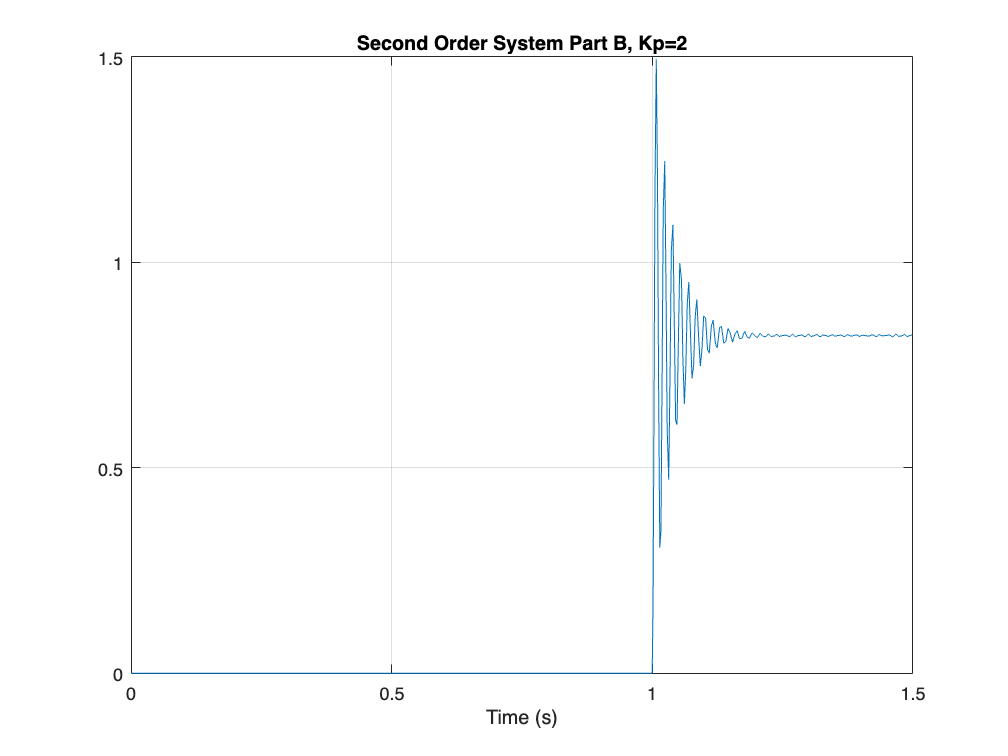

figure()
plot(P8.tout, P8.B)
title('Second Order System Part B, Kp=2')
xlabel('Time (s)')
grid on

The system has a larger percent overshoot in the Part B simulink, 81.3%, than the Part A simulink, 77.0%. The calculated percent overshoot from the initial parameters was 62.1%. It would make sense that Part B overshoots more than Part A since the Kp value is larger. 